# TESTS 2022- 2023

## Question 1.

1. Určete AUTOREGRESNÍ KOEFICIENTY segmentu signálu sigar-004.bin (binární soubor bez hlavičky, pro načtení použijte funkci loadbin, tj. např. sig-loadbin('sigar-004.bin');). Koeficienty počítejte autokorelační metodou (Yule-Walker), řád AR modelu volte p=12 a segment před výpočtem váhujte Hammingovým oknem.

% Načtení segmentu signálu
sig = loadbin('sigar-004.bin');

512 samples were read!



% Vážení segmentu Hammingovým oknem
w = hamming(length(sig));
sig_weighted = sig .* w;

% Výpočet autoregresních koeficientů pomocí funkce lpc
p = 12; % Řád AR modelu
[a, e] = lpc(sig_weighted, p);

% Zobrazení vypočítaných autoregresních koeficientů
disp('Autoregresní koeficienty (lpc):');

Autoregresní koeficienty (lpc):


disp(a);

    1.0000   -2.8000    3.4765   -2.6727    1.5240   -0.6839    0.5198   -0.4740   -0.0604    0.6906   -0.5379   -0.0483    0.1732




% Zobrazení výkonu chyby predikce
disp('Výkon chyby predikce (lpc):');

Výkon chyby predikce (lpc):


disp(e);

   9.6291e-07



2. Vypočtěte LPC spektrum (odhad spektrální výkonové hustoty na bázi LPC) v decibelech pro AR model s následujícími parametry:

- autoregresní koeficienty a = [ 1.00000 0.46636 0.57240 0.05272 -0.04452-0.02349 0.18349],

- výkon chyby predikce E = 4.7039e-06 LPC spektrum určete jako jednostranný odhad v 64 bodech.

-Zobrazte prvních 8 spektrálních komponent vypočítaného LPC spektra.

% Definice autoregresních koeficientů a výkonu chyby predikce
a = [1.00000 0.46636 0.57240 0.05272 -0.04452-0.02349 0.18349];
E = 4.7039e-06;

% Počet bodů pro výpočet frekvenční odezvy
wlen = 64;

% Výpočet frekvenční odezvy pomocí koeficientů AR modelu a výkonu chyby predikce
[H, f] = freqz(sqrt(E), a, wlen, 'half');

% Výpočet spektra v decibelech
spec = 10*log10(abs(H).^2);

% Zobrazení prvních 8 spektrálních komponent
prvni_8_spec = spec(1:8);
disp('Prvních 8 spektrálních komponent LPC spektra:');
disp(prvni_8_spec);

% Vykreslení prvních 8 spektrálních komponent pro lepší vizualizaci
figure;
stem(f(1:8), prvni_8_spec);
title('Prvních 8 spektrálních komponent LPC spektra');
xlabel('Frekvence (Hz)');
ylabel('Spektrum (dB)');
grid on;

3. Vypočtěte LPC spektrum (odhad spektrální výkonové hustoty na bázi LPC) v decibelech pro AR model s následujícími parametry:

- autoregresní koeficienty a = [ 1.00000 0.13245 0.59856 0.08645 -0.04674 -0.16135 -0.06211 ],

- výkon chyby predikce E = 9.7586e-06

LPC spektrum určete jako jednostranný odhad v 64 bodech.

-Zobrazte prvních 8 spektrálních komponent vypočítaného LPC spektra.

a = [1.00000 0.13245 0.59856 0.08645 -0.04674 -0.16135 -0.06211];
E = 9.7586e-06;

% Počet bodů pro výpočet frekvenční odezvy
wlen = 64;

% Výpočet frekvenční odezvy pomocí koeficientů AR modelu a výkonu chyby predikce
[H, f] = freqz(sqrt(E), a, wlen, 'half');

% Výpočet spektra v decibelech
spec = 10*log10(abs(H).^2);

% Zobrazení prvních 8 spektrálních komponent
prvni_8_spec = spec(1:8);
disp('Prvních 8 spektrálních komponent LPC spektra:');

Prvních 8 spektrálních komponent LPC spektra:


disp(prvni_8_spec);

  -53.8974
  -53.9225
  -53.9947
  -54.1059
  -54.2439
  -54.3945
  -54.5433
  -54.6769



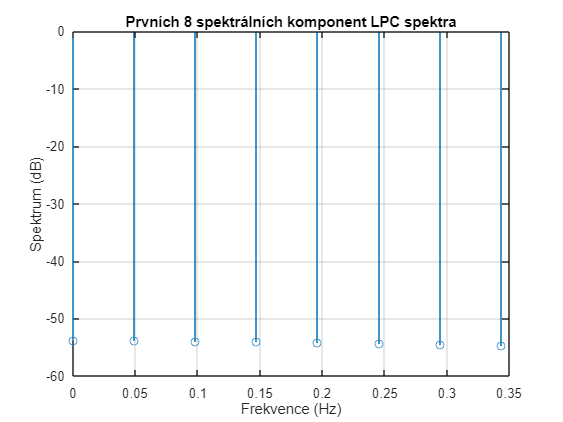


% Vykreslení prvních 8 spektrálních komponent pro lepší vizualizaci
figure;
stem(f(1:8), prvni_8_spec);
title('Prvních 8 spektrálních komponent LPC spektra');
xlabel('Frekvence (Hz)');
ylabel('Spektrum (dB)');
grid on;

## Question 2.

1. Určete výkonové spektrum v decibelech segmentu signálu frame-003.bin (Signál je uložen v binárním formátu bez hlavičky, pro načtení použijte funkci loadbin, tj. např. frame=loadbin('frame-003.bin');). Segment před výpočtem váhujte Hammingovým oknem. Zobrazte prvních 8 spektrálních komponent vypočítaného výkonového spektra.

 % Načtení segmentu signálu
frame = loadbin('frame-003.bin');

% Vytvoření Hammingova okna
w = hamming(length(frame));

% Vážení segmentu Hammingovým oknem
framew = w.*frame;

% Výpočet výkonového spektra
wlen = length(framew);
powerSpectrum = abs(fft(framew)).^2 / wlen;

% Převod výkonového spektra do decibelů
powerSpectrum_dB = 10*log10(powerSpectrum);

% Výběr a zobrazení prvních 8 spektrálních komponent
first8Components = powerSpectrum_dB(1:8);

disp('Prvních 8 spektrálních komponent výkonového spektra:');
disp(first8Components);

2. Určete výkon chyby predikce AR modelu segmentu signálu sigar-005.bin (binární soubor bez hlavičky, pro načtení použijte funkci loadbin, tj. např. sig=loadbin('sigar-005.bin');). AR model počítejte autokorelační metodou (Yule- Walker), řád AR modelu volte p-12 a segment před výpočtem váhujte Hammingovým oknem.

 % Načtení segmentu signálu
sig = loadbin('sigar-005.bin'); % Ujistěte se, že máte funkci loadbin

512 samples were read!



% Vážení segmentu Hammingovým oknem
w = hamming(length(sig));
sig_weighted = sig .* w;

% Výpočet AR modelu pomocí lpc funkce
p = 12; % Řád AR modelu
[a, variance] = lpc(sig_weighted, p);

% Výpis výkonu chyby predikce
disp('Výkon chyby predikce AR modelu:');

Výkon chyby predikce AR modelu:


disp(variance);

   3.3358e-07



3. Určete výkonové spektrum v decibelech segmentu signálu frame-007.bin (Signál je uložen v binárním formátu bez hlavičky, pro načtení použijte funkci loadbin, tj. např. frame=loadbin('frame-007.bin');). Segment před výpočtem váhujte Hammingovým oknem. Zobrazte prvních 8 spektrálních komponent vypočítaného výkonového spektra.

% Načtení segmentu signálu
frame = loadbin('frame-007.bin');

512 samples were read!



% Vytvoření Hammingova okna
w = hamming(length(frame));

% Vážení segmentu Hammingovým oknem
framew = w.*frame;

% Výpočet výkonového spektra
wlen = length(framew);
powerSpectrum = abs(fft(framew)).^2 / wlen;

% Převod výkonového spektra do decibelů
powerSpectrum_dB = 10*log10(powerSpectrum);

% Výběr a zobrazení prvních 8 spektrálních komponent
first8Components = powerSpectrum_dB(1:8);

disp('Prvních 8 spektrálních komponent výkonového spektra:');

Prvních 8 spektrálních komponent výkonového spektra:


disp(first8Components);

  -81.0164
  -61.3677
  -62.6932
  -59.8434
  -40.1529
  -36.4607
  -49.2368
  -62.3582



## Question 3.

1. Modelujte náhodný signál jako** AR proces 6. řádu **pro vzorkovací kmitočet fs = 16000 Hz, který má autoregresní koeficienty a = [ 1.00000 0.46636 0.57240 0.05272-0.04452-0.02349 0.18349], šestinásobný nulový bod v nule a násobnou konstantu rovnu G = 0.0021689. Model vybuďte bílým šumem s Gaussovým rozložením, který je dostupný v souboru un-excitation.bin (Signál je uložen v binárním formátu bez hlavičky, pro načtení použijte funkci loadbin, tj. např. un-loadbin ('un-excitation.bin');).

Pro modelovaný signál určetete vyhlazený odhad spektrální výkonové hustoty (PSD) Welchovou metodou v decibelech. Vyhlazený odhad počítejte s následujícími parametry:

- délka segmentu a počet bodů FFT wlen = 512, segmentace s 50% překryvem,

- implicitní váhování Hammingovým oknem,

- počítejte dvoustranný odhad PSD pro daný vzorkovací kmitočet, tj. u příslušné funkce volte parametry fs, 'twosided', 'psd'.

 % Definice vzorkovací frekvence a koeficientů AR procesu
fs = 16000;
a = [1.00000 0.46636 0.57240 0.05272 -0.04452 -0.02349 0.18349];
G = 0.0021689;

% Načtení bílého šumu (excitace)
un = loadbin('un-excitation.bin');

10000 samples were read!


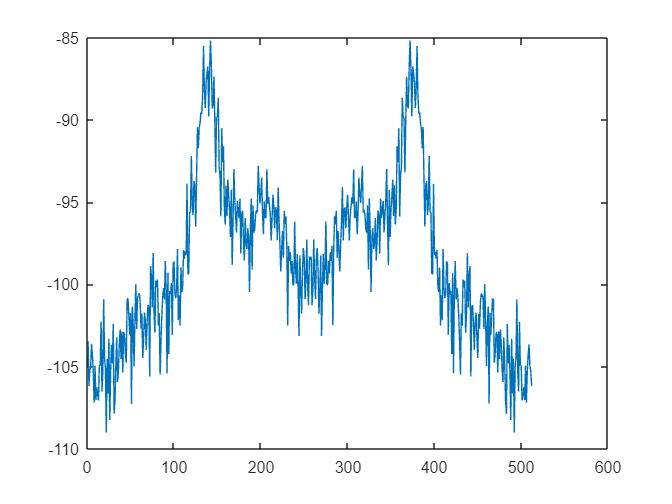


sig = filter(G, a, un);
wlen = 512;

%figure(2);
[pxx, f] = pwelch(sig,[],floor(wlen/2),wlen,fs,'twosided','psd');
PxxdB = 10*log10(pxx);
plot(PxxdB);

PxxdB(1:8)

ans =  -103.4476
 -106.1742
 -105.2366
 -104.9769
 -103.6431
 -104.3229
 -105.2799
 -107.1962


2. Modelujte náhodný signál jako** AR proces 6. řádu **pro vzorkovací kmitočet ffs = 16000 Hz , který má autoregresní koeficienty a = [1.00000 -2.54389 3.09003 -2.98049 2.61336 -1.54185 0.43826 ] , šestinásobný nulový bod v nule a násobnou konstantu rovnu G = 0.0023968 . Model vybuďte bílým šumem s Gaussovým rozložením, který je dostupný v souboru un-excitation.bin (Signál je uložen v binárním formátu bez hlavičky, pro načtení použijte funkci loadbin, tj. např. un-loadbin ('un-excitation.bin');).

Pro modelovaný signál určetete vyhlazený odhad spektrální výkonové hustoty (PSD) Welchovou metodou v decibelech. Vyhlazený odhad počítejte s následujícími parametry:

- délka segmentu a počet bodů FFT wlen = 512, segmentace s 50% překryvem,

- implicitní váhování Hammingovým oknem,

- počítejte dvoustranný odhad PSD pro daný vzorkovací kmitočet, tj. u příslušné funkce volte parametry fs, 'twosided', 'psd'.

 % Definice vzorkovací frekvence a koeficientů AR procesu
fs = 16000;
a = [1.00000 -2.54389 3.09003 -2.98049 2.61336 -1.54185 0.43826];
G = 0.0023968 ;

% Načtení bílého šumu (excitace)
un = loadbin('un-excitation.bin');

10000 samples were read!


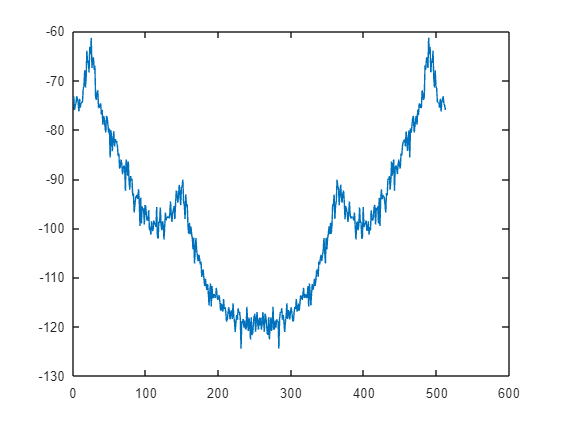


sig = filter(G, a, un);
wlen = 512;

%figure(2);
[pxx, f] = pwelch(sig,[],floor(wlen/2),wlen,fs,'twosided','psd');
PxxdB = 10*log10(pxx);
plot(PxxdB);

PxxdB(1:8)

ans =   -73.2420
  -75.9614
  -74.9828
  -74.6817
  -73.1938
  -73.7113
  -74.4843
  -76.2670


3. Modelujte náh. sig. pro fs=200hz jako **AR**** proces 3. řádu,  nulové body myzeros, troj. pol v nule a nás. konst.  rovnou jedné.** buďte bílým šumem un-excitation.bin. určete vyhlazený PSD Welchovou metodou v dB.

% Definice vzorkovací frekvence a pólů
fs = 200;
mypoles = [0.9, 0.8*exp(j*pi/4), 0.8*exp(-j*pi/4)];

% Převod pólů na koeficienty AR modelu
a = poly(mypoles);
b = 1; % Násobná konstanta rovna jedné

% Načtení bílého šumu
un = loadbin('un-excitation.bin');

10000 samples were read!



% Vygenerování náhodného signálu filtrováním bílého šumu
signal = filter(b, a, un);

% Parametry pro Welchův odhad PSD
wlen = 512;
noverlap = wlen / 2; % 50% překryv
window = hamming(wlen); % Hammingovo okno

% Výpočet vyhlazeného odhadu PSD
[pxx, f] = pwelch(signal, window, noverlap, wlen, fs, 'twosided', 'psd');

% Převod PSD do decibelů
pxx_dB = 10*log10(pxx)

pxx_dB =     0.3529
   -0.1388
    0.3991
    0.4272
    0.1019
   -1.1459
   -1.8730
   -3.1230
   -2.8306
   -2.8576


4.  Modelujte náhodný signál pro vzorkovací kmitočet fs = 200 Hz jako **MA**** proces 3. řádu, který má nulové body myzeros = [ 0.90.8*exp(j*pi/4) 0.8*exp(-j*pi/4) ] , trojnásobný pól v nule a násobnou konstantu rovnu jedné.** Model vybuďte bílým šumem sGaussovým rozložením, který je dostupný v souboru un-excitation.bin (Signál je uložen v binárním formátu bez hlavičky, pronačtení použijte funkci loadbin , tj. např. un=loadbin('un-excitation.bin'); ). Pro modelovaný signál určetete vyhlazený odhad spektrální výkonové hustoty (PSD) Welchovou metodou v decibelech

.Vyhlazený odhad počítejte s následujícími parametry:

- délka segmentu a počet bodů FFT wlen = 512,

- segmentace s 50% překryvem,

- implicitní váhování Hammingovým oknem,

- počítejte dvoustranný odhad PSD pro daný vzorkovací kmitočet, tj. u příslušné funkce volte parametry fs, 'twosided', 'psd'

% Definice vzorkovací frekvence a nulových bodů
fs = 200;
myzeros = [0.9, 0.8*exp(j*pi/4), 0.8*exp(-j*pi/4)];

% Převod nulových bodů na koeficienty MA procesu
b = poly(myzeros); % Koeficienty čitatele
a = 1; % Koeficient jmenovatele

% Načtení bílého šumu
un = loadbin('un-excitation.bin');

10000 samples were read!



% Generování náhodného signálu jako výstup MA procesu
y = filter(b, a, un);

% Parametry pro Welchův odhad PSD
wlen = 512;
noverlap = wlen / 2; % 50% překryv
window = hamming(wlen); % Hammingovo okno

% Výpočet vyhlazeného odhadu PSD
[pxx, f] = pwelch(y, window, noverlap, wlen, fs, 'twosided', 'psd');

% Převod PSD do decibelů
pxx_dB = 10*log10(pxx)

pxx_dB =   -51.1943
  -50.9177
  -50.8269
  -50.4239
  -49.6632
  -50.0862
  -50.0886
  -50.4785
  -49.1320
  -48.2337


4. Určete výkon chyby predikce AR modelu segmentu signálu sigar-009.bin (binární soubor bez hlavičky, pro načtení použijte funkci loadbin, tj. např. sig=loadbin('sigar-009.bin');). AR model počítejte autokorelační metodou (Yule- Walker), řád AR modelu volte p-12 a segment před výpočtem váhujte Hammingovým oknem.

 % Načtení segmentu signálu
sig = loadbin('sigar-009.bin'); % Ujistěte se, že máte funkci loadbin

512 samples were read!



% Vážení segmentu Hammingovým oknem
w = hamming(length(sig));
sig_weighted = sig .* w;

% Výpočet AR modelu pomocí lpc funkce
p = 12; % Řád AR modelu
[a, variance] = lpc(sig_weighted, p);

% Výpis výkonu chyby predikce
disp('Výkon chyby predikce AR modelu:');

Výkon chyby predikce AR modelu:


disp(variance);

   3.3069e-06



3. Určete výkonové spektrum v decibelech segmentu signálu frame-000.bin (Signál je uložen v binárním formátu bez hlavičky, pro načtení použijte funkci loadbin, tj. např. frame=loadbin('frame-000.bin');). Segment před výpočtem váhujte Hammingovým oknem. Zobrazte prvních 8 spektrálních komponent vypočítaného výkonového spektra.

% Načtení segmentu signálu
frame = loadbin('frame-000.bin');

512 samples were read!



% Vytvoření Hammingova okna
w = hamming(length(frame));

% Vážení segmentu Hammingovým oknem
framew = w.*frame;

% Výpočet výkonového spektra
wlen = length(framew);
powerSpectrum = abs(fft(framew)).^2 / wlen;

% Převod výkonového spektra do decibelů
powerSpectrum_dB = 10*log10(powerSpectrum);

% Výběr a zobrazení prvních 8 spektrálních komponent
first8Components = powerSpectrum_dB(1:8);

disp('Prvních 8 spektrálních komponent výkonového spektra:');

Prvních 8 spektrálních komponent výkonového spektra:


disp(first8Components);

  -52.5789
  -51.1486
  -51.3560
  -41.2650
  -35.7781
  -39.2494
  -50.7130
  -34.5135



## Question 4.

- Určete výkon chyby predikce AR modelu segmentu signálu sigar-007.bin (binární soubor bez hlavičky, pro načtení použijte funkci loadbin, tj. např. sig=loadbin('sigar-007.bin');). AR model počítejte autokorelační metodou (Yule- Walker), řád AR modelu volte p-12 a segment před výpočtem váhujte Hammingovým oknem.

 % Načtení segmentu signálu
sig = loadbin('sigar-004.bin'); % Ujistěte se, že máte funkci loadbin

512 samples were read!



% Vážení segmentu Hammingovým oknem
w = hamming(length(sig));
sig_weighted = sig .* w;

% Výpočet AR modelu pomocí lpc funkce
p = 12; % Řád AR modelu
[a, variance] = lpc(sig_weighted, p);

% Výpis výkonu chyby predikce
disp('Výkon chyby predikce AR modelu:');

Výkon chyby predikce AR modelu:


disp(variance);

   9.6291e-07



2. Určete výkon chyby predikce AR modelu segmentu signálu sigar-005.bin (binární soubor bez hlavičky, pro načtení použijte funkci loadbin, tj. např. sig=loadbin('sigar-005.bin');). AR model počítejte autokorelační metodou (Yule- Walker), řád AR modelu volte p-12 a segment před výpočtem váhujte Hammingovým oknem.

 % Načtení segmentu signálu
sig = loadbin('sigar-005.bin'); % Ujistěte se, že máte funkci loadbin

512 samples were read!



% Vážení segmentu Hammingovým oknem
w = hamming(length(sig));
sig_weighted = sig .* w;

% Výpočet AR modelu pomocí lpc funkce
p = 12; % Řád AR modelu
[a, variance] = lpc(sig_weighted, p);

% Výpis výkonu chyby predikce
disp('Výkon chyby predikce AR modelu:');

Výkon chyby predikce AR modelu:


disp(variance);

   3.3358e-07



3. Vypočtěte LPC spektrum (odhad spektrální výkonové hustoty na bázi LPC) v decibelech pro AR model s následujícími parametry:

- autoregresní koeficienty a = [1.00000 -2.45209 2.18820 -1.03447 1.01896 -1.11572 0.46416 ] ,

- výkon chyby predikce E = 8.2103e-06

LPC spektrum určete jako jednostranný odhad v 64 bodech a zobrazte prvních 8 spektrálních komponent.

% Definice autoregresních koeficientů a výkonu chyby predikce
a = [1.00000 -2.45209 2.18820 -1.03447 1.01896 -1.11572 0.46416];
E = 8.2103e-06;

% Počet bodů pro výpočet frekvenční odezvy
wlen = 64;

% Výpočet frekvenční odezvy pomocí koeficientů AR modelu a výkonu chyby predikce
[H, f] = freqz(sqrt(E), a, wlen, 'half');

% Výpočet spektra v decibelech
spec = 10*log10(abs(H).^2);

% Zobrazení prvních 8 spektrálních komponent
prvni_8_spec = spec(1:8);
disp('Prvních 8 spektrálních komponent LPC spektra:');

Prvních 8 spektrálních komponent LPC spektra:


disp(prvni_8_spec);

  -27.6384
  -27.3386
  -26.3982
  -24.6715
  -21.8148
  -17.0712
  -12.1396
  -17.2245



﻿4. **Modelujte náhodný signál pro vzorkovací kmitočet fs = 200 Hz jako MA proces 4. řádu, který má nulové body myzeros = [0.8*exp(j*pi/4) 0.8*exp(-j*pi/4) 0.95*exp(j*5*pi/6) 0.95*exp(-j*5*pi/6)], čtyřnásobný pól v nule a násobnou konstantu rovnu jedné. Model vybudte bílým šumem s Gaussovým rozložením, který je dostupný v souboru un-excitation.bin (Signál je uložen v binárním formátu bez hlavičky, pro načtení použijte funkci loadbin, tj. např. un-loadbin('un-excitation.bin');).**

Pro modelovaný signál určetete vyhlazený odhad spektrální výkonové hustoty (PSD) Welchovou metodou v decibelech. Vyhlazený odhad počítejte s následujícími parametry:

- délka segmentu a počet bodů FFT wien = 512,

-segmentace s 50% překryvem,

- implicitní váhování Hammingovým oknem,

- počítejte dvoustranný odhad PSD pro daný vzorkovací kmitočet, tj. u příslušné funkce volte parametry fs, 'twosided', 'psd'.

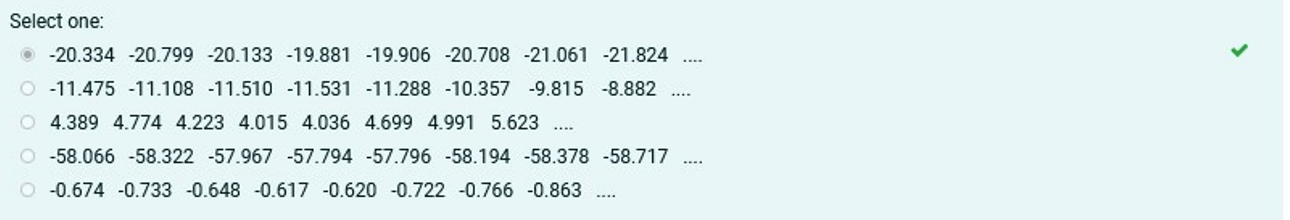

% Define the parameters
fs = 200; % Sampling frequency (Hz)
p = 4; % Order of the MA process
myzeros = [0.8*exp(1i*pi/4), 0.8*exp(-1i*pi/4), 0.95*exp(5i*pi/6), 0.95*exp(5i*pi/6)];
wlen = 512;

a = 1;
b = poly(myzeros);

% Load the Gaussian white noise from the binary file
gaussian_noise = loadbin('un-excitation.bin');%0.5*randn(wlen,1);

10000 samples were read!



% Create the MA process
ma_signal = filter(b, a, gaussian_noise);

% Estimate the power spectral density (PSD) using Welch's method
[pxx, f] = pwelch(ma_signal, wlen, wlen/2, wlen, fs, 'twosided', 'psd');

% Convert PSD to decibels
psd_in_db = 10*log10(pxx);
psd_in_db(1:8)

ans =   -20.3311
  -20.8331
  -20.1895
  -19.9640
  -20.0212
  -20.8500
  -21.2328
  -22.0231


7. Modelujte nízkokofrekvenční (NF) náhodný signál jako AR proces 1. řádu s šířkou pásma B = 500 Hz pro vzorkovací kmitočet fs = 16000 Hz, nulovým bodem v nule a násobnou konstantou rovnou jedné. Model vybuďte bílým šumem s Gaussovým rozložením, který je dostupný v souboru un-excitation.bin (Signál je uložen v binárním formátu bez hlavičky, pro načtení použijte funkci loadbin, tj. např. un-loadbin('un-excitation.bin');).

Pro modelovaný signál určetete vyhlazený odhad spektrální výkonové hustoty (PSD) Welchovou metodou v decibelech. Vyhlazený odhad počítejte s následujícími parametry:

- délka segmentu a počet bodů FFT wlen = 512, 

-segmentace s 50% překryvem,

- implicitní váhování Hammingovým oknem,

- počítejte dvoustranný odhad PSD pro daný vzorkovací kmitočet, tj. u příslušné funkce volte parametry fs,twosided','psd'.

% AR proces: b=1;
% MA proces: a=1;

% Parametry pro AR proces
fs = 16000; % Vzorkovací kmitočet
B = 500; % Šířka pásma

% Koeficienty AR procesu 1. řádu
a = exp(-pi * B / fs);
A = [1, -a]; % AR koeficienty
B = 1; % Násobná konstanta rovna jedné

% Načtení bílého šumu
un = loadbin('un-excitation.bin');

10000 samples were read!



% Vygenerování NF náhodného signálu filtrováním bílého šumu
nf_signal = filter(B, A, un);

% Parametry pro Welchův odhad PSD
wlen = 512; % Délka segmentu a počet bodů FFT
noverlap = wlen / 2; % 50% překryv
window = hamming(wlen); % Hammingovo okno

% Výpočet vyhlazeného odhadu PSD
[pxx, f] = pwelch(nf_signal, window, noverlap, wlen, fs, 'twosided', 'psd');

% Převod PSD do decibelů
pxx_dB = 10*log10(pxx)

pxx_dB =   -23.9743
  -24.4739
  -23.9633
  -23.9768
  -24.3538
  -25.6742
  -26.4608
  -27.7889
  -27.5596
  -27.6512


8. Modelujte náh. sig. pro fs=200hz jako MA proces 3. řádu nulové body myzeros, troj. pol v nule a nás. konst.  rovnou jedné. buďte bílým šumem un-excitation.bin. určete vyhlazený PSD Welchovou metodou v dB.

% Modelujte náhodný signál pro fs = 200 Hz jako MA proces 3. řádu
fs = 200;
myzeros = [0.9, 0.8*exp(j*pi/4), 0.8*exp(-j*pi/4)]; % Definice nulových bodů
b = poly(myzeros); % Koeficienty MA procesu
a = 1; % Trojnásobný pól v nule a násobná konstanta rovna jedné
G = 1;

% Načtení bílého šumu
sig = loadbin('un-excitation.bin');

10000 samples were read!


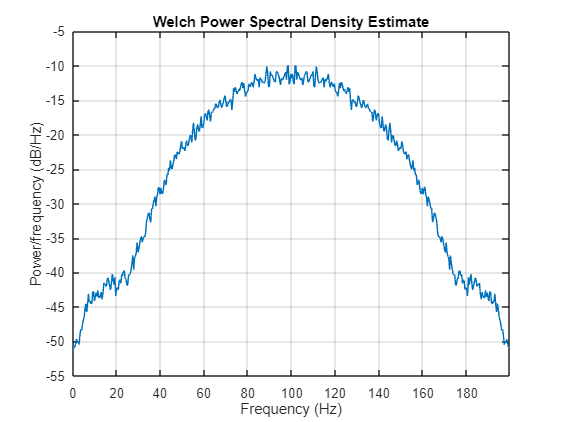


% Generování náhodného signálu
y = G*filter(b, a, sig);

% Parametry pro Welchův odhad PSD
wlen = 512;

% Výpočet a vizualizace vyhlazeného PSD Welchovou metodou v dB
figure;
pwelch(y, wlen, wlen/2, wlen, fs, 'twosided', 'psd');

1.

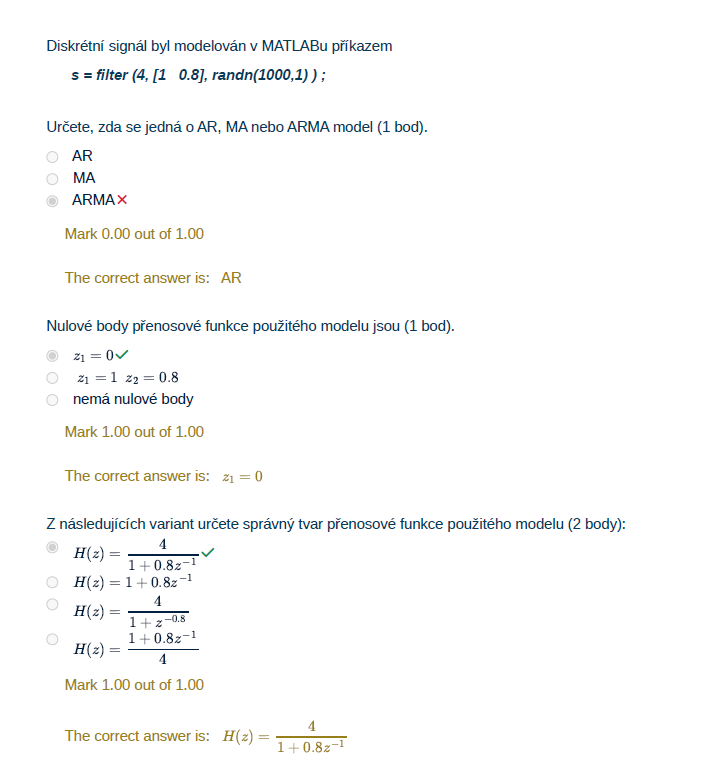

1. **Typ modelu**

   Příkaz v MATLABu `filter([4, [1 -0.8]], randn(1000,1));` používá filtr k aplikaci na bílý šum. Vektor `[4, [1 -0.8]]` určuje koeficienty filtru, kde první hodnota odpovídá koeficientu `b0 = 4` (MA části) a zbylé hodnoty `[1 -0.8]` odpovídají koeficientům `a0 = 1` a `a1 = -0.8` (AR části). Tento filtr tedy představuje AR model prvního řádu, protože vektor `a` má více než jeden člen a je použit na vstupní šum. MA model by použil pouze `b` koeficienty a ARMA model kombinaci obou.

2. **Nulové body přenosové funkce**

   Přenosová funkce je určena koeficienty filtru. Pro AR část máme `a0 = 1` a `a1 = -0.8`, což znamená, že přenosová funkce bude mít tvar `H(z) = b0 / (a0 - a1 * z^(-1))`. V tomto případě máme nulový bod v `z = 0`, což odpovídá koeficientu `b0 = 4`, a pól je dán hodnotou `z = 1/a1 = 1/0.8`.

3. **Správný tvar přenosové funkce**

   Správná přenosová funkce je dána poměrem `H(z) = b0 / (a0 - a1 * z^(-1))`, kde `b0 = 4`, `a0 = 1`, a `a1 = -0.8`. Když dosadíme koeficienty, dostaneme `H(z) = 4 / (1 + 0.8 * z^(-1))`, což je správná odpověď zadaná v testu.

2.

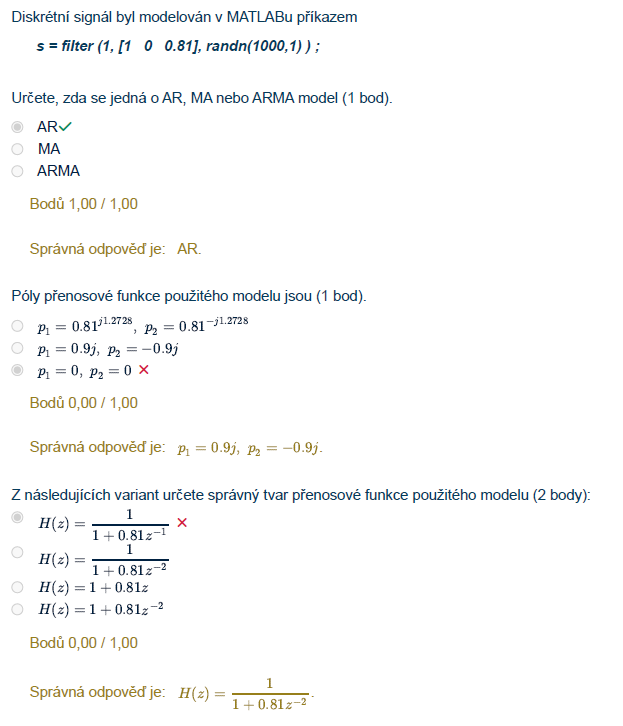

1. **Typ modelu:** 

   V kódu `s = filter([1 0 0.81], randn(1000,1));` se používá funkce `filter` s koeficienty `[1 0 0.81]`, což naznačuje, že se jedná o AR model, protože všechny koeficienty filtru jsou na straně jmenovatele přenosové funkce, což je typické pro AR modely. Koeficienty čitatele `[1]` představují násobnou konstantu rovnu jedné, bez dalších MA koeficientů. Proto je správná odpověď "AR".

2. **Póly přenosové funkce:**

   Koeficienty `[1 0 0.81]` naznačují, že existuje jediný pól, který je určen rovnicí \(z^2 - 0.81 = 0\). Póly této kvadratické rovnice jsou \(z = \sqrt{0.81} = 0.9\) a \(z = -\sqrt{0.81} = -0.9\), což odpovídá možnostem uvedeným ve druhé otázce testu. Tedy správná odpověď je \( p_1 = 0.9, p_2 = -0.9 \).

3. **Tvar přenosové funkce:** 

   Přenosová funkce filtru je dána jako \( H(z) = \frac{1}{1 + 0z + 0.81z^{-2}} \). Pokud přeneseme členy zpět na pravou stranu rovnice, dostaneme \( H(z) = \frac{1}{1 - 0.81z^{-2}} \). To je ve shodě s poslední možností uvedenou ve třetí otázce testu a správnou odpovědí je \( H(z) = \frac{1}{1 - 0.81z^{-2}} \).

3. 

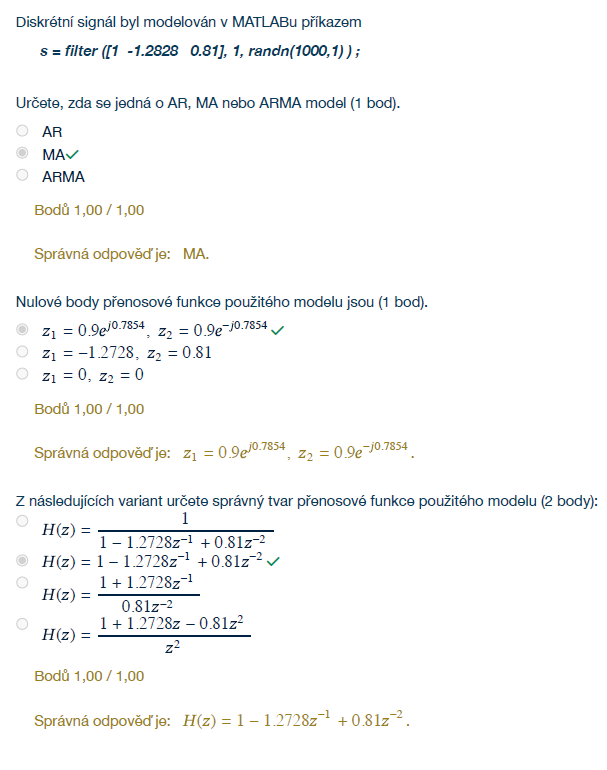

1. **Typ modelu:**

   Kód `s = filter([1 -1.2828 0.81], 1, randn(1000,1));` používá filtr s koeficienty v čitateli přenosové funkce, a žádnými koeficienty v jmenovateli kromě `1`. To znamená, že se jedná o MA model (Moving Average), protože členy filtru jsou aplikovány na šum přímo, což odpovídá konceptu MA modelu, kde výstup je lineární kombinací současného a předchozích vzorků bílého šumu.

2. **Nulové body přenosové funkce:**

   Koeficienty `[1 -1.2828 0.81]` v čitateli určují nulové body přenosové funkce. V tomto případě nulové body odpovídají kořenům rovnice z^2 - 1.2828z + 0.81 = 0, které jsou `z1 = 0.9e^j0.7854, z2 = 0.9e^-j0.7854`. Tyto nulové body představují body, kde přenosová funkce dosahuje nuly.

3. **Správný tvar přenosové funkce:**

   Správný tvar přenosové funkce filtru je založen na jeho koeficientech. Přenosová funkce MA modelu je dána jako `H(z) = b0 + b1*z^-1 + b2*z^-2`, kde b0, b1, b2 jsou koeficienty v čitateli. Protože máme koeficienty `[1 -1.2828 0.81]`, správná přenosová funkce v tomto případě je `H(z) = 1 - 1.2728z^-1 + 0.81z^-2`, což je možnost druhá z nabízených odpovědí.

Z výše uvedených bodů je zřejmé, že správné odpovědi na otázky jsou:

1. **MA** (Moving Average model).

2. **Nulové body jsou:** `z1 = 0.9e^j0.7854`, `z2 = 0.9e^-j0.7854`.

3. **Správný tvar přenosové funkce:** `H(z) = 1 - 1.2728z^-1 + 0.81z^-2`.

4.

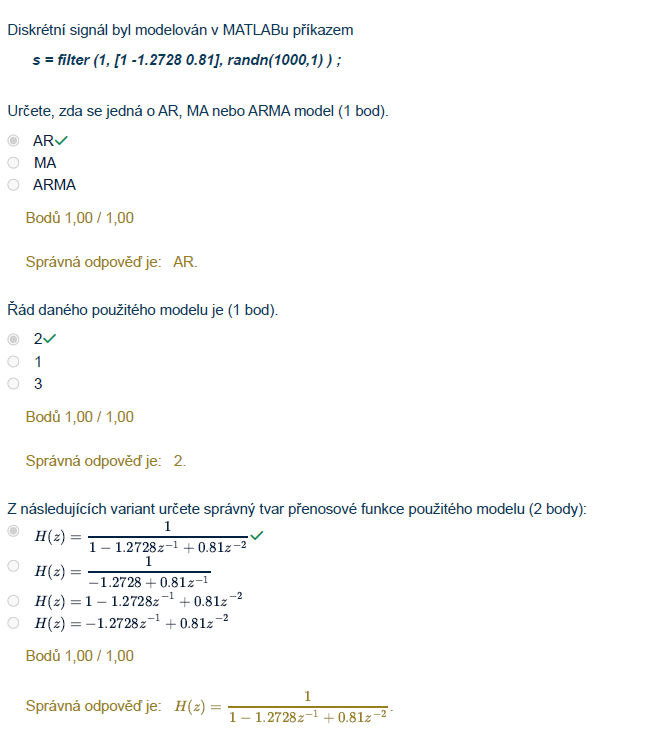

5.

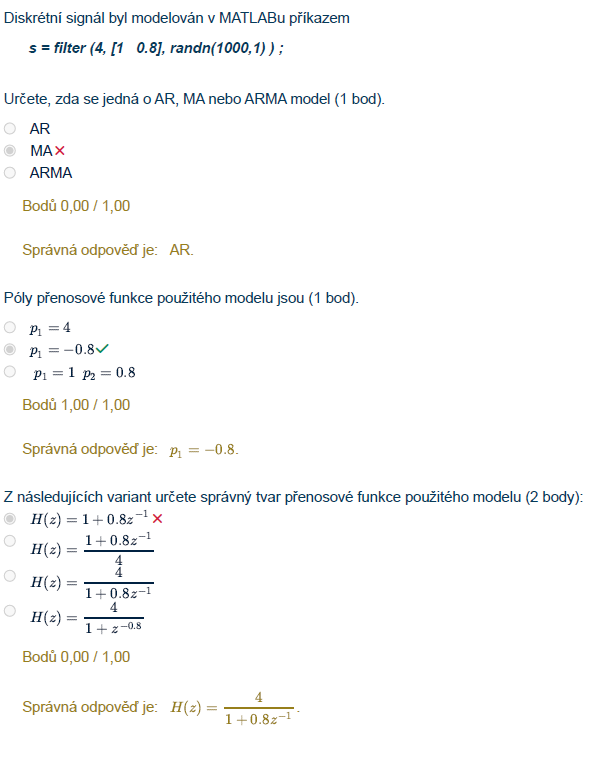

6. 

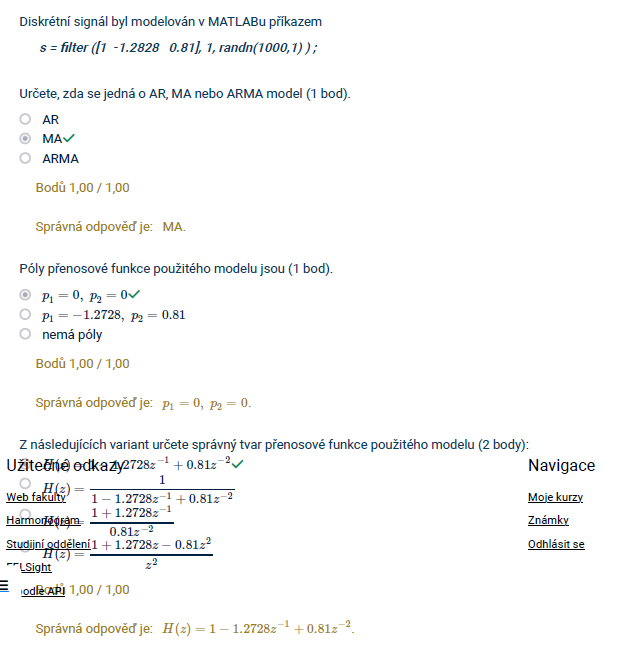

b = [1  -1.2828   0.81]

b =     1.0000   -1.2828    0.8100


a = 1

a = 1

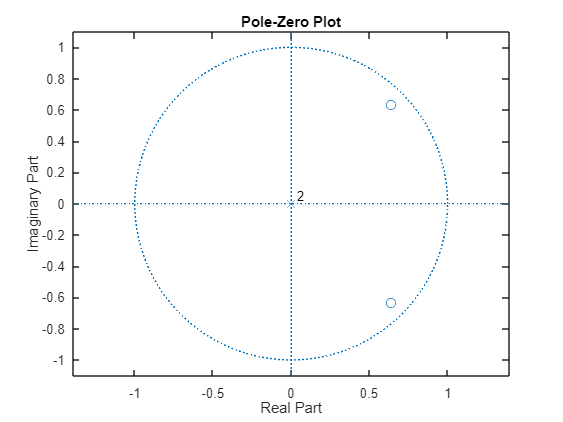

 s = filter (b, a, randn(1000,1) ) ;

fvtool(b,a) % info o filtru

[z,p,k]  = zplane(b,a);


rts = roots(b)

rts =    0.6414 + 0.6314i
   0.6414 - 0.6314i


r1_ang = angle(rts(1))

r1_ang = 0.7775

r1_mag = abs(rts(1))

r1_mag = 0.9000


r2_ang = angle(rts(1))

r2_ang = 0.7775

r2_mag = abs(rts(2))

r2_mag = 0.9000